# Lens Systems

## The Paraxial Approximation

The paraxial approximation entails substituting the sines, cosines and tangents of angles with the angles themselves (when the angles are measured in radians). We will now check what is the error incurred when we do such an approximation. 

First we create a vector of angle values.

theta = [0:0.01:60];

Now we calculate the sine and tangent with these angle values. 

sin_theta = sin(theta*pi/180);
tan_theta = tan(theta*pi/180);  %Note the conversion from degrees to radians. 

Now we calculate the error introduced by the paraxial approximation.

error_sin = abs(sin_theta-theta*pi/180);
error_tan = abs(tan_theta-theta*pi/180);

Here is a plot of the error. 

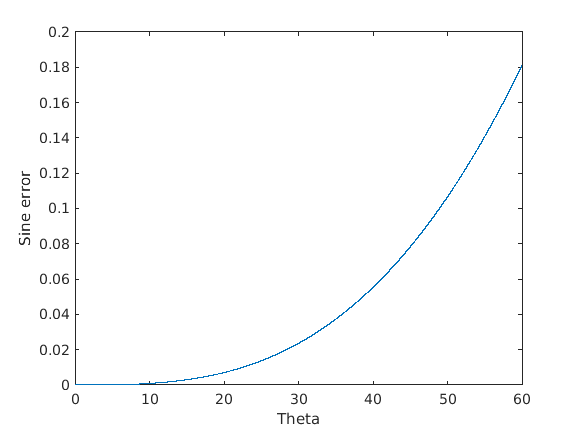

plot(theta,error_sin);
xlabel('Theta');
ylabel('Sine error');

Error for the tangents.

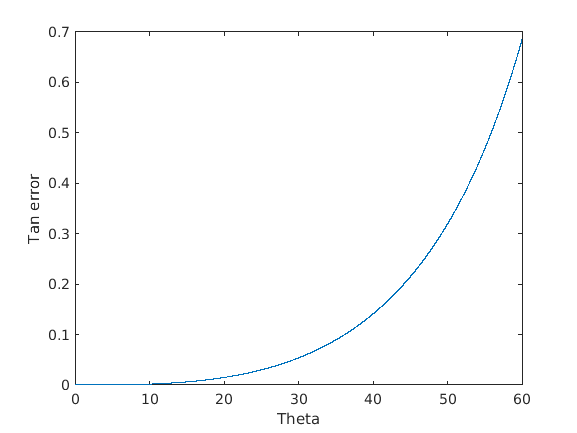

plot(theta, error_tan);
xlabel('Theta');
ylabel('Tan error');

Note how the error rises faster for the tangent than for the sine. 

So we see that for small angles, the paraxial approximation introduces a smaller error. We thus have to be careful in using these formulae for large angle rays. 

### Task 1 - Small angle limit

Say for a given problem, we need a paraxial error than 0.001. By moving the slider below, find the maximum angle for which this holds. x is specified in degrees.

x =9.81;
error_sin = abs(x*pi/180-sin(x*pi/180))

error_sin = 8.3532e-04

## Studying image formation using paraxial ray matrices

In class we studied how the transfer of rays through free space and optical media can be modeled in the paraxial region using matrices. Specifically, the translation matrix can be given as

$T=\left\lbrack \begin{array}{cc}
1 & D\\
0 & 1
\end{array}\right\rbrack$, and the lens matrix is given as $L=\left\lbrack \begin{array}{cc}
1 & 0\\
-\frac{1}{f} & 1
\end{array}\right\rbrack$. For the case of imaging using a thin lens as shown in the image below, the matrix equation relating the object and image height and angles is given by 

$\left\lbrack \begin{array}{c}
x_I \\
\theta_{I\;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & v\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 0\\
-\frac{1}{f} & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & -u\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_O \\
\theta_O 
\end{array}\right\rbrack$.

Note the use of the signs, keeping with the all-positive convention. 

An axial object $\left(x_O =0\right)$gives rise to an axial image $\left(x_I =0\right)$. It can then be shown that this leads to the familiar equation


$$\frac{1}{v}-\frac{1}{u}=\frac{1}{f}\ldotp$$


Keep in mind that to arrive at this equation, we have already invoked the sign convention for $u$. 

### Task 2 - Single lens imaging

The code below shows an implementation of the matrix equation for the above single lens system. Substituting different values for $u,\;v,\;x$ and $\theta ,$ verify the following.

- Rays coming from infinity in the object space will converge at the focus in the image space.

- Rays emanating from an axial object located at the focus in the object space will become parallel in the image space. 

- When the object is located at a distance twice the focal length away from the lens in the object space, the image is formed at twice the focal length in the image space. Check if the size of the image formed agrees with your understanding.

x0 = 1;
theta0 = 10*pi/180;

XO = [x0;theta0];

f = 10;     %Focal length
u = -15;    %Object distance
v = 20;     %Location of the image plane

T1 = [1, -u;0, 1];  %Note the use of the sign convention as per the definitions above.
L1 = [1, 0; -1/f, 1];
T2 = [1, v; 0, 1];  %v is the location of the image plane. v here is used as a parameter.

XI = T2*L1*T1*XO

XI =    -0.1273
   -0.1873


### Task 3 - Two-lens system

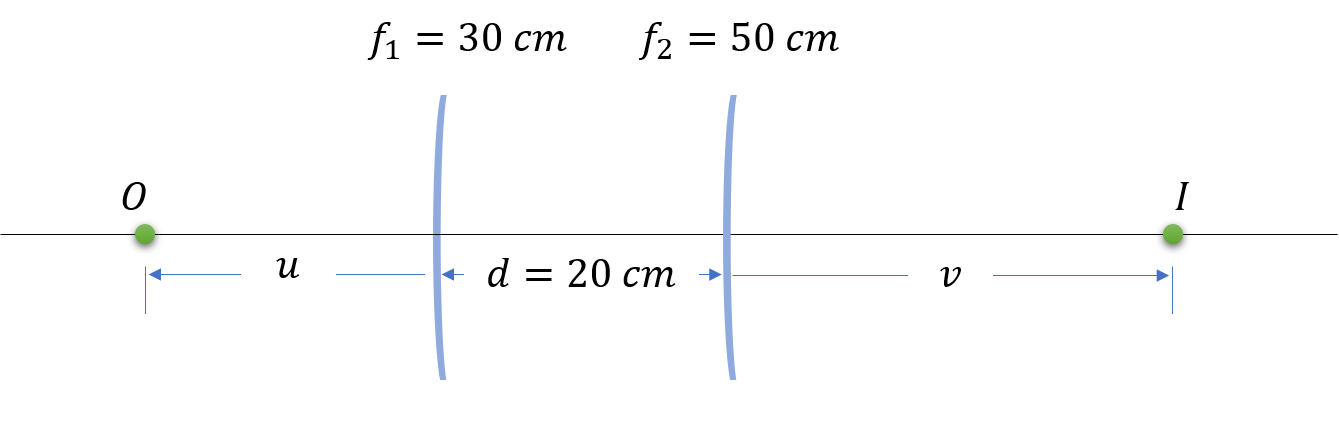

For the system above, write a code to calculate the system matrix (i.e. the matrix describing the ray transfer from P to Q). 

- Verify the correctness of the code by checking that the value of the focal length/power of the lens combination obtained using the matrix is the same as you would get by using the known formula directly.

- Put $d=0$ in the system matrix and check the value of the focal length. 

- The system matrix can be written in a generalized form [1]

$S=\left\lbrack \begin{array}{cc}
a & -b\\
-c & d
\end{array}\right\rbrack$.

            Then, the object and image planes can be related via the equation

$v=\frac{b+a\ldotp u}{d+c\ldotp u}$,

            and the magnification can be given by 

$M=d+c\ldotp u$.

            For the given system, plot the three graphs $v\;\textrm{vs}\ldotp u$, $M\;\textrm{vs}\ldotp u$, and $v\;\textrm{vs}\ldotp M$. The last graph is called the throw        vs. magnification curve. What can you infer from these graphs? (Note $u$ can vary from $-\infty \;$to $0$. You will have to define a vector of values for u, as we did for some variables in the last tutorial.) 

When you find the system matrix, store the values of its elements in the variables $a,b,c,d,$ so that you can easily use it in this and the next exercise.

### Task 4 - Cardinal points

Using the terminology for the system matrix $S$ as shown in the previous problem, one can define the locations of the principal and nodal planes with respect to the first last vertices of the lens system as


$$u_{P,N} =\frac{1-d}{c},v_{P,N} =\frac{a-1}{c}\ldotp$$


- Find the cardinal points of the above system. Sketch the location of these planes for yourself.

- Verify that your answer is correct.

- Replace the second lens with a diverging lens of the same power, and place it within the back focal length of the first lens so that the system still forms an image. Find the cardinal points of the above system and sketch the location of these planes. What could be the possible use of such a system? (Hint - what is the effective focal length of this system, if you measure the focal length with respect to the principal planes?). 

## Task 5 - The Smart-phone Microscope

Nowadays there are many clip-on smartphone attachments available which allow you to obtain highly magnified images (as much as 780X). In it simplest form, such an attachment comprises of a single ball lens, which is mounted in front of the smartphone camera - effectively forming a two-lens system. The principle then is straightforward - using the ball- and smartphone-lens combination to reduce the effective focal length, such that a higher magnification can be achieved. 

A typical smartphone camera has a nominal focal length of 25 mm, where the distance between the lens and CCD sensor of the camera can be taken to be approx. 4 mm. You have a ball lens of diameter 3 mm. 

- For a separation of roughly 5 mm between the back vertex of the ball lens and the front surface of the camera lens, calculate the magnification of the lens combination. 

- Can you obtain a higher magnification using this lens combination? 

- **Optional **- This single ball lens configuration is not technically a microscope, but just a two-lens combination with a shorter focal length. Design a microscope attachment for the smartphone above ***with two ball lenses*** of diameters 3 mm and 1 mm, and calculate its effective magnification. Sketch the ray diagram for this configuration. 

## References

[1]. Ghatak, "Optics", 4e, Tata McGraw Hill, 2009.